**The simulations of the dynamics after inhibition of Pol II.**

**For Figure 5c.**

% Basic paramters
load ../Parameter_determination/Basic_parameters.mat

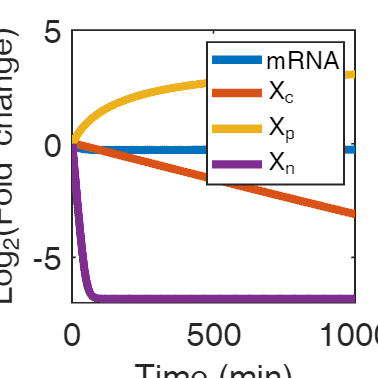

para1=[para_opt,5.8262];

% Symbolic solutions
load ../Solve_values/Solve_values.mat
syms_solve=[Xn_pre,Xc_pre,Xp_pre,Yn_pre,Yp_pre];


%Pol II inhibition
[kn_wt,kn_tot,y_wt,y_tot]=RNAPdeplete_noFC(para1,syms_solve);
%y:[mn mc Xn Xc Xp Yn Yp]
temp_m=(y_tot(:,1)+y_tot(:,2))/(y_wt(1)+y_wt(2));
temp_Xc=y_tot(:,4)/y_wt(4);
temp_Xp=y_tot(:,5)/y_wt(5);
temp_Xn=y_tot(:,3)/y_wt(3);
temp_Yn=y_tot(:,6)/y_wt(6);
temp_Yp=y_tot(:,7)/y_wt(7);
temp_kn=kn_tot/kn_wt;

% Plot
colors=["#0072BD"
    "#D95319"
    "#EDB120"
    "#7E2F8E"
    "#77AC30"
    "#4DBEEE"
    "#A2142F"
    '#FF0000'
    '#00FF00'
    '#0000FF'
    '#00FFFF'
    '#FF00FF'
    '#FFFF00'
    '#000000'
    '#FFFFFF'];

fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);

p1=plot(1:2000,log2(temp_m), ...
    'DisplayName',"mRNA", ...
    "Color",colors(1),...
    "LineWidth",5);
hold on
p2=plot(1:2000,log2(temp_Xc), ...
    'DisplayName',"X_c", ...
    "Color",colors(2),...
    "LineWidth",5);
hold on
p3=plot(1:2000,log2(temp_Xp), ...
    'DisplayName',"X_p", ...
    "Color",colors(3),...
    "LineWidth",5);
p4=plot(1:2000,log2(temp_Xn), ...
    'DisplayName',"X_n", ...
    "Color",colors(4),...
    "LineWidth",5);
hold off

xlim([0,1000])
ylim([-7,5])
set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
legend([p1 p2 p3 p4],"FontSize",15)
xlabel('Time (min)','interpreter','tex','FontSize',20);
ylabel('Log_2(Fold change)','interpreter','tex','FontSize',20);

function dydt = diffun(y,para)
%%% Differential equations of the system

%y:[mn mc Xn Xc Xp Yn Yp]
mn=y(1);
mc=y(2);
Xn=y(3);
Xc=y(4);
Xp=y(5);
Yn=y(6);
Yp=y(7);

%para:[k0 Kx Ky Km am ax ay bm bx Xt Yt Kv]

k0=para(1);
Kx=para(2);
Ky=para(3);
Km=para(4);
am=para(5);
ax=para(6);
ay=para(7);
bm=para(8);
bx=para(9);
%Xt=para(10);
%Yt=para(11);
Kv=para(12);


dydt = zeros(7,1);
%dydt:[dmndt dmcdt dXndt dXcdt dXpdt dYndt dYpdt]

Vn=2.8;%fL
Vc=37.2;%fL

kn=(k0*Vn/(Vn+Kv))*(Xp/(Xp+Kx*Vn))*Vn*Km/(Vn*Km+mn)*Yp/(Yp+Ky*Vn);

dydt(1)=kn-am*(Yn/Vn)*mn;
dydt(2)=am*(Yn/Vn)*mn-bm*(Xc/Vc)*mc;
dydt(3)=kn-ax*Xn;
dydt(4)=ax*Xn-bx*Xc;
dydt(5)=bx*Xc-kn;
dydt(6)=kn-ay*Yn;
dydt(7)=ay*Yn-kn;

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



function [kn_wt,kn_tot,y_wt,y_tot]=RNAPdeplete_noFC(para0,syms_solve)
%%% The function calculating the values of molecules.

%Numerically solve the values of molecules in WT cells
syms k0 Kx Ky Km am ax ay bm bx Xt Yt Vn Vc Kv
para_sym=[k0 Kx Ky Km am ax ay bm bx Xt Yt Vn Vc Kv];
para_num=[para0(1:11),2.8,37.2,para0(12)];
%para:[k0 Kx Ky Km am ax ay bm bx Xt Yt Kv]
temp1=double(subs(syms_solve,para_sym,para_num));% Xn Xc Xp Yn Yp
temp1=temp1(~any(temp1<0,2),:);
temp2=[2.8*para0(7)/para0(5),37.2*para0(9)/para0(8)];% mn mc

y_wt=[temp2,temp1];


%paramters
k0=para0(1);
Kx=para0(2);
Ky=para0(3);
Km=para0(4);
%am=para0(5);
%ax=para0(6);
%ay=para0(7);
%bm=para0(8);
%bx=para0(9);
%Xt=para0(10);
%Yt=para0(11);
Kv=para0(12);
mn=y_wt(1);
%mc=y_wt(2);
%Xn=y_wt(3);
%Xc=y_wt(4);
Xp=y_wt(5);
%Yn=y_wt(6);
Yp=y_wt(7);
Vn=2.8;%fL
%Vc=37.2;%fL

kn_wt=(k0*Vn/(Vn+Kv))*(Xp/(Xp+Kx*Vn))*Vn*Km/(Vn*Km+mn)*Yp/(Yp+Ky*Vn);

%shut off the transcription using a big Kv
para1=para0;
para1(12)=1e3;
Kv=para1(12);

%Calculate the values of molecules after inhibition
tspan=[1:1:2000];
[~,y_tot]=ode15s(@(t,y)diffun(y,para1),tspan,y_wt);

%Calculate the kn after inhibition
kn_tot=zeros(1,length(tspan));
for i=1:length(tspan)
    mn=y_tot(i,1);
    %mc=y_tot(i,2);
    %Xn=y_tot(i,3);
    %Xc=y_tot(i,4);
    Xp=y_tot(i,5);
    %Yn=y_tot(i,6);
    Yp=y_tot(i,7);
    kn_tot(i)=(k0*Vn/(Vn+Kv))*(Xp/(Xp+Kx*Vn))*Vn*Km/(Vn*Km+mn)*Yp/(Yp+Ky*Vn);
end


end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
